# Example 2.2: Machine Status as Uniform RV

Note: this script reproduces Example 2.2 (Section 2.1.1) of **Statistics for Chemical Engineers**: the weekly status of a machine (failure or normal). Victor Z UW-Madison, 2020 example machine failure as uniform RV

clc; clear all; close all hidden;

rng(0);        
z = 52;       % weeks
t = 0:1:z;    % time vector
n=length(t);  % number of times
N=3;          % number of samples

## Machine status over 156 weeks

generate random failure sequences

ny=0;
for k=1:N

y = unidrnd(2,1,n); 
y = y-1;
ny=sum(y)+ny;

subplot(2,1,1)
for j=1:length(y)
if y(j)==1 %failure
    scatter(t(j),k,'blacko','MarkerFaceColor','black','MarkerEdgeColor','black') 
    hold on
else       %normal
    scatter(t(j),k,'blacko','MarkerFaceColor','w','MarkerEdgeColor','black')
    hold on
end
end
grid on
axis([min(t) max(t) 0 4])
set(gca,'yticklabels',{'','Year 1 ','Year 2 ','Year 3 ',''})
xlabel('$\textrm{Time [weeks]}$','interpreter','Latex','Fontsize',14)
box on
end

failure_rate = ny/(N*z)

failure_rate = 0.5064

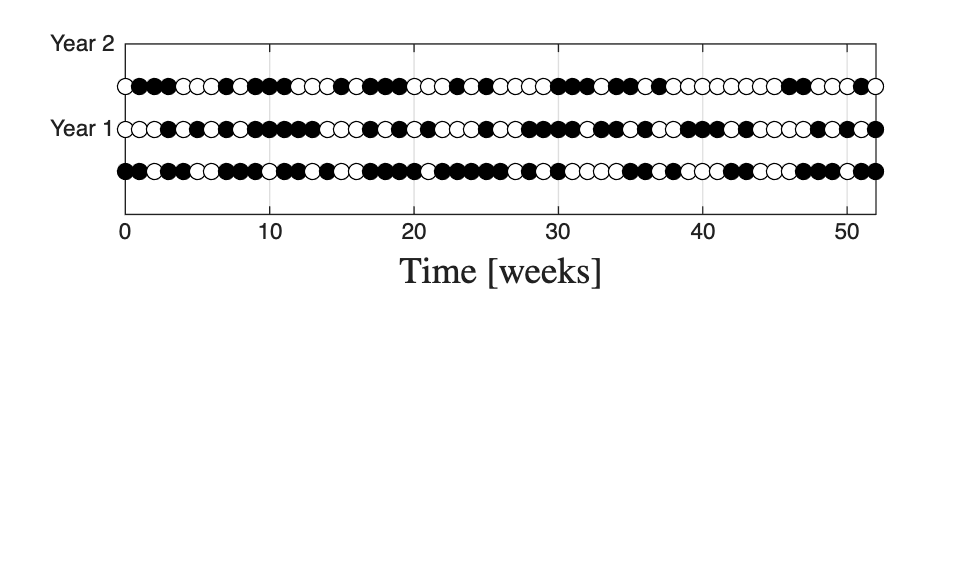


print -depsc ch2_unifprocess.eps

## Note

As in the book, the machine failed in 79 of 156 weeks: the empirical probabilities (0.5064 and 0.4936) suggest that its status behaves as a uniform RV U(0,1).